# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials.
Read 0 textures.
***Scene parsed.


The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

thisR

thisR =   recipe with properties:

            camera: [1×1 struct]
           sampler: [1×1 struct]
              film: [1×1 struct]
            filter: []
        integrator: [1×1 struct]
          renderer: []
            lookAt: [1×1 struct]
             scale: [0×3 double]
             world: {'WorldBegin'}
            lights: []
    transformTimes: []
         inputFile: '/Users/zhenglyu/Desktop/Research/git/iset3d-v4/data/V4/sphere/sphere.pbrt'
        outputFile: '/Users/zhenglyu/Desktop/Research/git/iset3d-v4/local/sphere/sphere.pbrt'
      renderedFile: ''
           version: 4
         materials: [1×1 struct]
          textures: [1×1 struct]
            assets: [1×1 tree]
          exporter: 'C4D'
             media: []
          metadata: [1×1 struct]
         recipeVer: 2
           verbose: 2


## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

pointLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',pointLight, 'add');

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces
thisR.set('render type', {'radiance', 'depth'});

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera.  Thus, we are rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

[scene, result] = piRender(thisR);

 Rsync Put: rsync -r -t /Users/zhenglyu/Desktop/Research/git/iset3d-v4/local/sphere/ zhenglyu@muxreconrt.stanford.edu:/home/zhenglyu/iset/iset3d-v4/local/sphere/
Pushed scene to remote in:   0.29
Render: docker --context zheng-muxreconrt exec -it  pbrt-gpu-zhenglyu12447 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Successfuly rendered remotely in:   2.38
 Rsync Pull: rsync -r zhenglyu@muxreconrt.stanford.edu:/home/zhenglyu/iset/iset3d-v4/local/sphere/renderings/ /Users/zhenglyu/Desktop/Research/git/iset3d-v4/local/sphere/renderings
Retrieved output in:   0.29
Complete render took: 3.53e+00 seconds.*** Rendering time for sphere:  3.5 sec ***



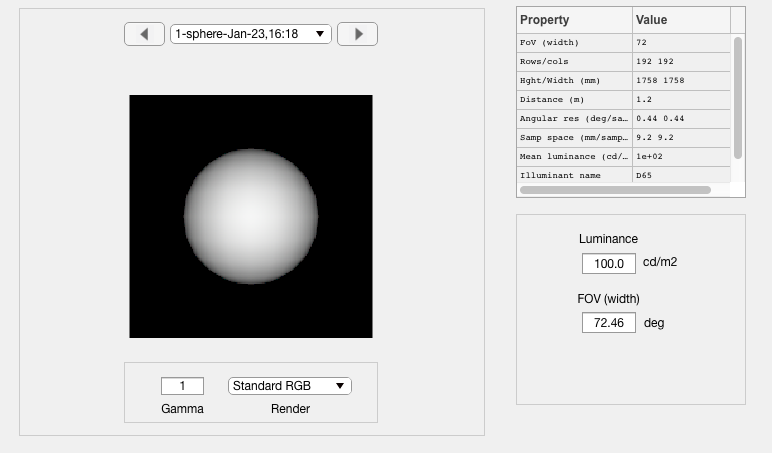

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

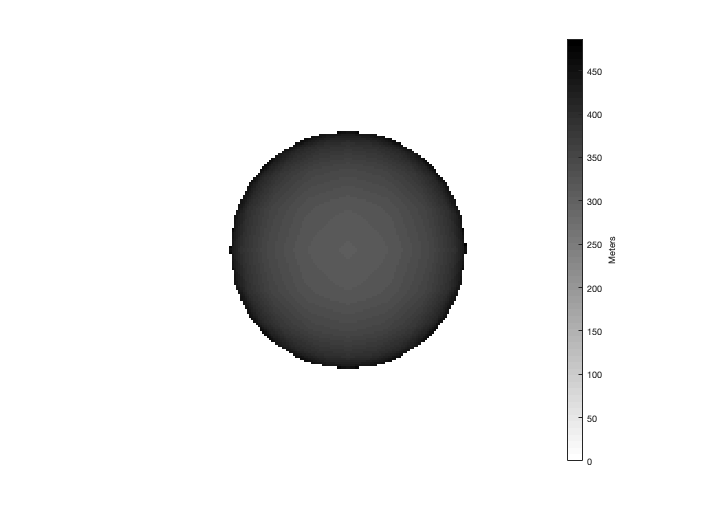

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

distantLight = piLightCreate('distant','type','distant',  'spd', [9000],  'cameracoordinate', true);
thisR.set('light',pointLight.name, 'delete');
thisR.set('light',distantLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

 Rsync Put: rsync -r -t /Users/zhenglyu/Desktop/Research/git/iset3d-v4/local/sphere/ zhenglyu@muxreconrt.stanford.edu:/home/zhenglyu/iset/iset3d-v4/local/sphere/
Pushed scene to remote in:   0.29
Render: docker --context zheng-muxreconrt exec -it  pbrt-gpu-zhenglyu12447 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Successfuly rendered remotely in:   2.42
 Rsync Pull: rsync -r zhenglyu@muxreconrt.stanford.edu:/home/zhenglyu/iset/iset3d-v4/local/sphere/renderings/ /Users/zhenglyu/Desktop/Research/git/iset3d-v4/local/sphere/renderings
Retrieved output in:   0.31
Complete render took: 3.61e+00 seconds.*** Rendering time for sphere:  3.6 sec ***



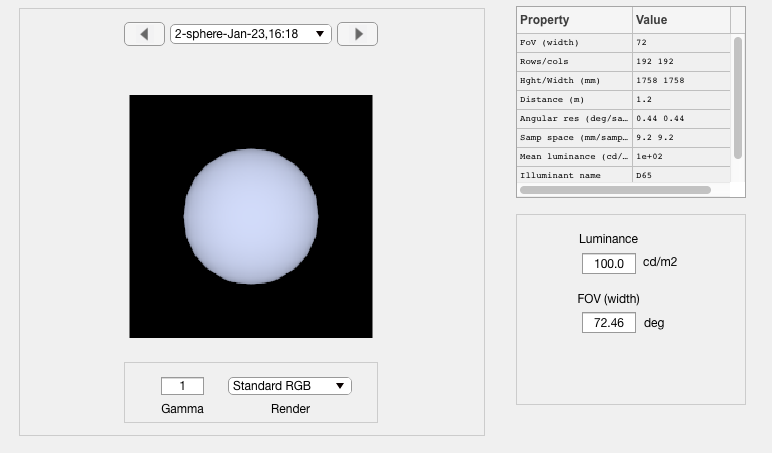

scene = piWRS(thisR);